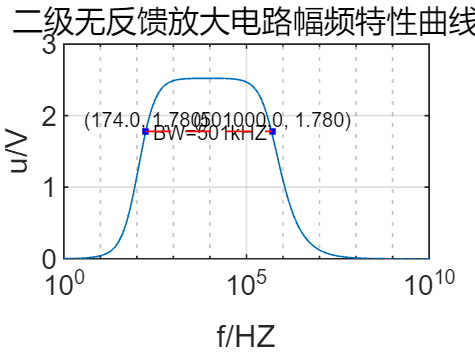

x = [1.0, 1.2589254117941673, 1.5848931924611136, 1.99526231496888, 2.5118864315095806, 3.16227766016838, 3.9810717055349736, 5.011872336272725, 6.309573444801935, 7.9432823472428185, 10.000000000000005, 12.58925411794168, 15.848931924611145, 19.95262314968881, 25.118864315095824, 31.622776601683825, 39.81071705534977, 50.11872336272729, 63.0957344480194, 79.43282347242825, 100.00000000000014, 125.89254117941691, 158.4893192461116, 199.52623149688827, 251.18864315095843, 316.2277660168385, 398.10717055349795, 501.1872336272732, 630.9573444801945, 794.3282347242831, 1000.000000000002, 1258.9254117941698, 1584.8931924611168, 1995.2623149688839, 2511.8864315095857, 3162.2776601683863, 3981.0717055349814, 5011.872336272734, 6309.5734448019475, 7943.2823472428345, 10000.000000000025, 12589.254117941706, 15848.931924611177, 19952.62314968885, 25118.86431509587, 31622.776601683883, 39810.71705534984, 50118.72336272738, 63095.734448019524, 79432.82347242841, 100000.00000000033, 125892.54117941715, 158489.3192461119, 199526.23149688868, 251188.64315095893, 316227.76601683913, 398107.1705534988, 501187.2336272742, 630957.3444801958, 794328.2347242847, 1000000.0000000041, 1258925.4117941724, 1584893.19246112, 1995262.314968888, 2511886.4315095907, 3162277.660168393, 3981071.70553499, 5011872.336272745, 6309573.444801961, 7943282.347242852, 10000000.000000047, 12589254.117941732, 15848931.92461121, 19952623.149688892, 25118864.315095924, 31622776.60168395, 39810717.05534992, 50118723.36272748, 63095734.448019646, 79432823.47242856, 100000000.00000052, 125892541.17941739, 158489319.2461122, 199526231.49688905, 251188643.1509594, 316227766.0168397, 398107170.55349946, 501187233.6272751, 630957344.4801968, 794328234.7242861, 1000000000.0000058, 1258925411.7941747, 1584893192.461123, 1995262314.9688916, 2511886431.5095954, 3162277660.168399, 3981071705.5349975, 5011872336.272755, 6309573444.801973, 7943282347.2428665, 10000000000.000065];

y = [1.811042255246606, 2.839415772884642, 4.418396328251151, 6.797452252308637, 10.293221895259641, 15.280227833641636, 22.185127983136294, 31.52027823273912, 44.000353952682275, 60.768576610256666, 83.74169540431984, 116.08813256880715, 162.8541390790547, 231.70060774973007, 333.5776331025593, 482.9158440826901, 696.5620815598852, 990.4816527700937, 1373.8348254889786, 1841.9043893236328, 2371.5565924927423, 2923.1572001811046, 3450.0457820775823, 3912.0933183343864, 4286.400997910281, 4569.622120806854, 4772.537105566351, 4912.090380482123, 5005.315830547346, 5066.365809231646, 5105.818202900408, 5131.091824703575, 5147.18863058401, 5157.398273709891, 5163.849795028089, 5167.905726741028, 5170.42951610186, 5171.961120777547, 5172.829229490157, 5173.220483030311, 5173.2190891541095, 5172.824776963366, 5171.952765604503, 5170.415765087956, 5167.884395574461, 5163.818242380019, 5157.354586860028, 5147.135549300189, 5131.047935620336, 5105.847464375546, 5066.651201122445, 5006.333583580038, 4914.996446350173, 4779.949927505086, 4587.000374401133, 4323.952784132694, 3986.3291914708752, 3582.9485133128214, 3136.9964512825964, 2680.137650237706, 2242.792717427542, 1846.6518739785583, 1502.5608201729663, 1212.5161843168125, 973.0157024022197, 777.9505828424398, 620.4966802524524, 494.1343756579191, 393.09557526359504, 312.48988261189714, 248.2732670352867, 197.15146510854584, 156.4653776177914, 124.08042651852793, 98.28866339913625, 77.72602393235805, 61.30430130353198, 48.156406993269194, 37.59336614248937, 29.07171001585315, 22.16998338761922, 16.572306366250768, 12.054713892252158, 8.467242135846634, 5.705683228400635, 3.6761629669984908, 2.267860984370252, 1.3487048552382461, 0.7822069863974612, 0.44910809585963246, 0.25961799059471236, 0.153714840758234, 0.09467938136677174, 0.06139884872925174, 0.04221307680184984, 0.0308271282586077, 0.023867214364465945, 0.01950870544213953, 0.016737114921095076, 0.014963060599113526, 0.013827323233711372];

 

y1=[];
for i=1:length(y)
    num=y(1,i);
    num=num/2051;
    y1=[y1,num];
end

y1_smooth = smooth(y1, 100, 'loess'); % 使用局部加权回归进行平滑
    % 绘图
figure;
semilogx(x,y1);
title("二级无反馈放大电路幅频特性曲线");
xlabel('f/HZ');
ylabel('u/V');
    text(174,1.78 , sprintf('(%0.1f, %0.3f)',174, 1.78), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center','FontSize',6);
    text(501000,1.78 , sprintf('(%0.1f, %0.3f)',501000, 1.78), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center','FontSize',6);
    text(10000,1.6 , sprintf('BW=501kHZ'), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center','FontSize',6);

grid on
hold on
plot(174,1.78,'b.');
plot(501000,1.78,'b.');
hold on
line([174, 501000], [1.78,1.78], 'Color', 'r', 'LineStyle', '--');

使用matlab直接读取仿真数据

x

x = 1.0e+10 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% 设置导入选项并导入数据
opts2 = spreadsheetImportOptions("NumVariables", 2);

% 指定工作表和范围
opts2.Sheet = "Sheet1";
opts2.DataRange = "A2:B102";

% 指定列名称和类型
opts2.VariableNames = ["X____1___V_12__", "Y____1___V_12__"];
opts2.VariableTypes = ["double", "double"];

% 导入数据
cffdq = readtable("C:\Users\nchm\Desktop\demo\波动光学\cffdq.xlsx", opts2, "UseExcel", false);

% 清除临时变量
clear opts2

% 显示结果
cffdq

cffdq = 101×2 table
    X____1___V_12__    Y____1___V_12__
    _______________    _______________

             1             7.9297     
        1.2589             9.9764     
        1.5849             12.547     
        1.9953             15.769     
        2.5119             19.801     
        3.1623             24.827     
        3.9811             31.056     
        5.0119             38.711     
        6.3096              47.99     
        7.9433             59.017     
            10              71.74     
        12.589              85.83     
        15.849             100.61     
        19.953              115.1     
        25.119             128.27     
        31.623             139.36     


data_part = table2array(cffdq(:, :))

data_part = 1.0e+10 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


sheet_x = data_part(:,1)'

sheet_x = 1.0e+10 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


sheet_y = data_part(:,2)'

sheet_y =     7.9297    9.9764   12.5465   15.7693   19.8011   24.8269   31.0565   38.7107   47.9904   59.0169   71.7401   85.8304  100.6078  115.1000  128.2748  139.3560  148.0268  154.4091  158.8879  161.9227  163.9295  165.2347  166.0745  166.6110  166.9522  167.1685  167.3055  167.3920  167.4467  167.4813  167.5030  167.5168  167.5254  167.5308  167.5341  167.5360  167.5370  167.5373  167.5369  167.5357  167.5335  167.5298  167.5238  167.5141  167.4988  167.4744  167.4354  167.3730  167.2725  167.1094


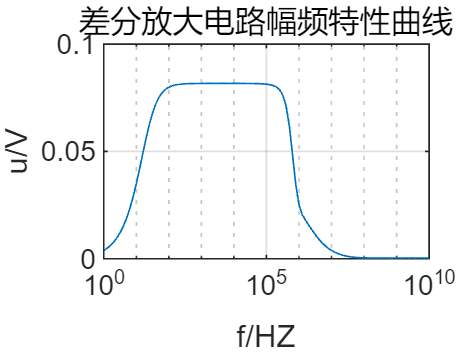

y1=[];
for i=1:length(sheet_y)
    num=sheet_y(1,i);
    num=num/2051;
    y1=[y1,num];
end

y1_smooth = smooth(y1, 100, 'loess'); % 使用局部加权回归进行平滑
    % 绘图
figure;
semilogx(sheet_x,y1);
title("差分放大电路幅频特性曲线");
xlabel('f/HZ');
ylabel('u/V');
    % text(174,1.78 , sprintf('(%0.1f, %0.3f)',174, 1.78), ...
    %     'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center','FontSize',6);
    % text(501000,1.78 , sprintf('(%0.1f, %0.3f)',501000, 1.78), ...
    %     'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center','FontSize',6);
    % text(10000,1.6 , sprintf('BW=501kHZ'), ...
    %     'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center','FontSize',6);

grid on
hold on

% plot(174,1.78,'b.');
% plot(501000,1.78,'b.');
% hold on
% line([174, 501000], [1.78,1.78], 'Color', 'r', 'LineStyle', '--');